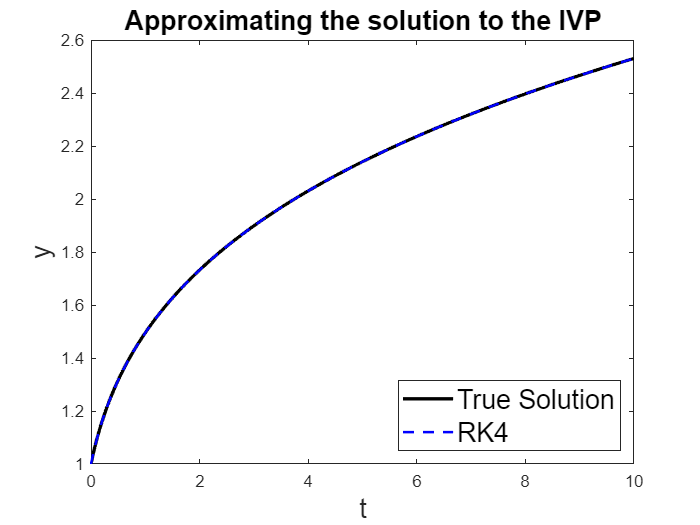

f = @(t,y) 1 / y.^3;
t0 = 0;
tf = 10;
alpha = 1; 
N = (tf-t0)/(10^-3);
true_f = @(t) (4*t+1).^(1/4);

% f = @(t,y)sqrt(t)./sin(y);
% true_f = @(t)acos(cos(1)-(2/3)*t.^(3/2));
% t0 = 0;
% tf = 1.5;
% alpha = 1;
% N2 = (tf-t0)/(10^-3);

[y_rk4, t_rk4] = rk4(f,t0,tf,alpha,N);
figure

plot(t0:0.01:tf,true_f(t0:0.01:tf),'k','LineWidth',2); hold on;
plot(t_rk4,y_rk4,'b--','LineWidth',1.5);
title('Approximating the solution to the IVP','FontSize',16);
xlabel('t', 'FontSize', 16);
ylabel('y', 'FontSize', 16);
legend('True Solution','RK4', 'FontSize', 16, 'Location', 'southeast');

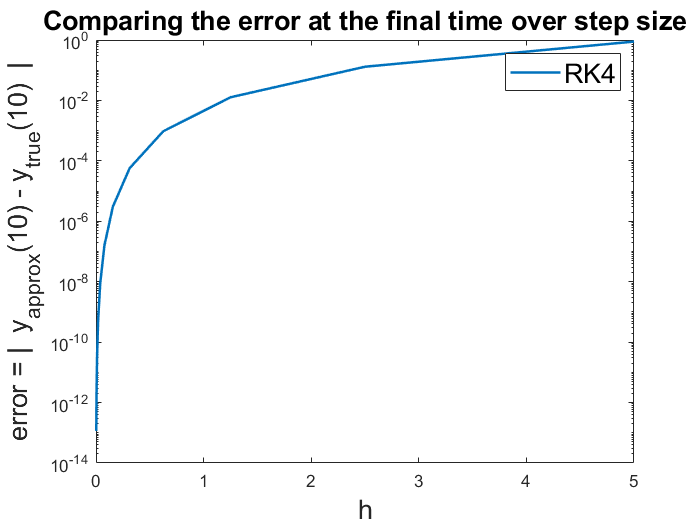


N2_vals = 2.^[1:12]; % This becomes a list of [2,4,8,16,32,64,128]
for itr = 1:length(N2_vals)
    N = N2_vals(itr);
    [y2_rk4_c,~] = rk4(f,t0,tf,alpha,N);
    errors_rk4(itr) = abs(y2_rk4_c(end)- true_f(tf));
end
figure
semilogy((tf-t0)./N2_vals,errors_rk4,'LineWidth',1.5);
% loglog((tf-t0)./N2_vals,errors_rk4,'LineWidth',1.5);
title('Comparing the error at the final time over step size','FontSize',16);
xlabel('h','FontSize',16)
ylabel('error = |  y_{approx}(10) - y_{true}(10)  |','FontSize',16);
legend('RK4','FontSize',16)